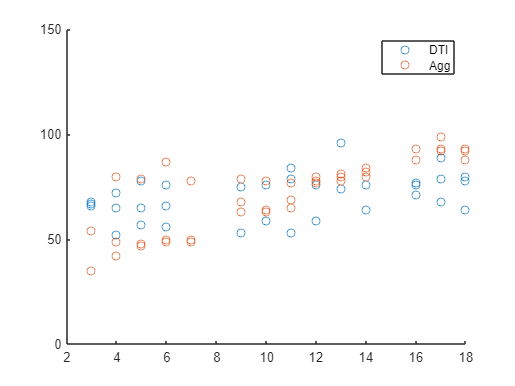

DT_Data = readmatrix('DT_Multiple_DTI_Single_Data.csv');
DT_Data_Aggregate = readmatrix('DT_Aggregate_Single_Data.csv');
Conv_Data = readmatrix('Conv_Multiple_DTI_Single_Data.csv');
Conv_Data_Aggregate = readmatrix('Conv_Aggregate_Single_Data.csv');

scatter(DT_Data(:,1),DT_Data(:,6)), hold on
scatter(DT_Data_Aggregate(:,1),DT_Data_Aggregate(:,6)), hold off
legend('DTI','Agg')
ylim([0 150])

%lsline

scatter(Conv_Data(:,4),Conv_Data(:,6)), hold on
%ylim([0 200])
%lsline, hold on
scatter(Conv_Data_Aggregate(:,4),Conv_Data_Aggregate(:,6))
%lsline
legend('DTI','DTI LOB','Agg','Agg LOB')

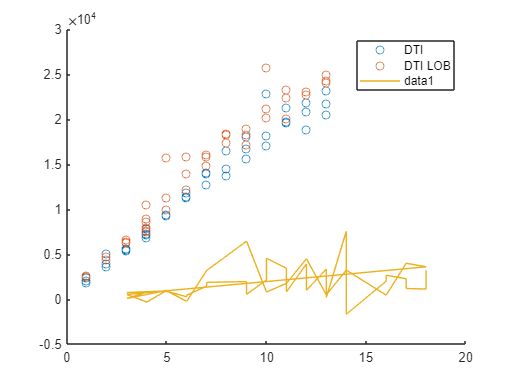


test = Conv_Data_Aggregate(:,6) - Conv_Data(:,6);
plot(Conv_Data(:,1),test(:,1))

%}
%{
DT_Data = readmatrix('DT_Single_DTI_Single_Data.csv');
DT_Time = DT_Data(:,6);
boxplot(DT_Time)

%DT_Time.Properties.VariableNames = ["DT Total Time Taken"];
Conv_Data = readmatrix('Conv_Single_DTI_Single_Data_File.csv');
Conv_Time = Conv_Data(:,6);
%Conv_Time.Properties.VariableNames = ["Conv Total Time Taken"];
BoxPlotData = [DT_Time, Conv_Time];
boxplot(BoxPlotData, 'Labels',{'DT Total Time', 'Conv Total Time'})

scatter3(T,'NumberOfDTs','NumberOfDataPoints','TotalTimeTaken','filled', ...
    'ColorVariable','TotalTimeTaken');
s.SizeData = 100;
colorbar

T = readtable('Conv_Single_DTI_Single_Data.csv');

scatter3(T,'NumberOfDTs','NumberOfDataPoints','TotalTimeTaken','filled', ...
    'ColorVariable','TotalTimeTaken');
s.SizeData = 100;
colorbar
%}